# Experiment 2: CNN (Whole Image)

## Clean environment

close all;
clear variables;
clc;
rng(42);

## Set folder path

folder = "C:\Users\u3253992\workspace\computer-vision\assignment_1\u3253992_assgn_1_best\CUB_200_2011\";

## Load dataset

[trainingImageNames, validationImageNames, testImageNames, classNames, imageClassLabels] = loadDataset(folder);

No bounding Box


numClasses = height(classNames);

## Create datastores

disp('Training set class distribution:');

Training set class distribution:


trainingImageDS = createImageDatastore(trainingImageNames, folder);

    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  
     017      34  
     018      26  
     019      35  
     020      35  
     021      36  
     022      34  
     023      35  
     024      31  
     025      36  
     026      36  
     027      36  
     028      35  
     029      36  
     030      36  
     031      36  
     032      32  
     033      35  
     034      35  
     035      36  
     036      36  
     037      35  
     038      36  
     039      35  
     040      36  
     041      36  
     042      36  
     043      35  
     044      36  
     045      36  
     046      36  
     047      36  



disp('Validation set class distribution:');

Validation set class distribution:


validationImageDS = createImageDatastore(validationImageNames, folder);

    Label    Count
    _____    _____

     001      12  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  
     017      12  
     018      10  
     019      12  
     020      12  
     021      12  
     022      11  
     023      12  
     024      11  
     025      12  
     026      12  
     027      12  
     028      12  
     029      12  
     030      12  
     031      12  
     032      11  
     033      12  
     034      12  
     035      12  
     036      12  
     037      12  
     038      12  
     039      12  
     040      12  
     041      12  
     042      12  
     043      12  
     044      12  
     045      12  
     046      12  
     047      12  



disp('Test set class distribution:');

Test set class distribution:


testImageDS = createImageDatastore(testImageNames, folder);

    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  
     017      11  
     018       9  
     019      12  
     020      12  
     021      12  
     022      11  
     023      12  
     024      10  
     025      12  
     026      12  
     027      12  
     028      12  
     029      12  
     030      12  
     031      12  
     032      10  
     033      12  
     034      12  
     035      12  
     036      12  
     037      12  
     038      12  
     039      12  
     040      12  
     041      12  
     042      12  
     043      12  
     044      12  
     045      12  
     046      12  
     047      12  


## Resize image datastores and combine them with the labels

targetSize = [128, 128];
% targetSize = [224, 224];
% targetSize = [256, 256];
% targetSize = [229, 299];
% targetSize = [384, 384];

trainCDS = resizeCombineDatastore(trainingImageDS, targetSize);
valCDS = resizeCombineDatastore(validationImageDS, targetSize);
testCDS = resizeCombineDatastore(testImageDS, targetSize);

## Show images

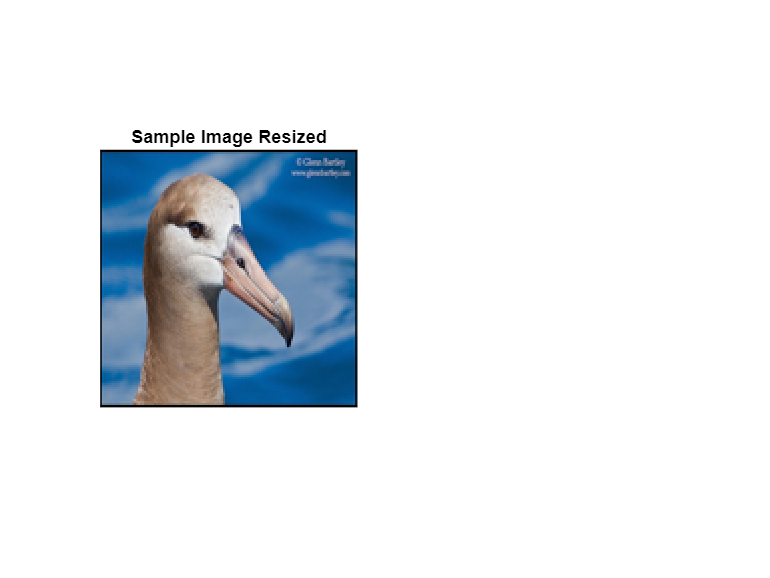

showImage(trainCDS)

## Enables GPU

[device, useGPU] = enableGPU();

✅ GPU found and ready:
  CUDADevice with properties:

                 Name: 'NVIDIA GeForce RTX 3070'
                Index: 1 (of 1)
    ComputeCapability: '8.6'
          DriverModel: 'WDDM'
          TotalMemory: 8589410304 (8.59 GB)
      AvailableMemory: 7439773696 (7.44 GB)
      DeviceAvailable: true
       DeviceSelected: true

  Show 

## CNN - Convolutional Neural Network

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:37 |        0.00% |        0.80% |       6.5946 |       8.4173 |          0.0010 |
|       1 |           2 |       00:00:37 |        0.00% |              |       7.8432 |              |          0.0010 |
|       1 |           3 |       00:00:37 |        3.12% |              |       8.9173 |              |          0.0010 |
|       1 |           4 |       00:00:37 |        3.12% |              |      10.0443 |   

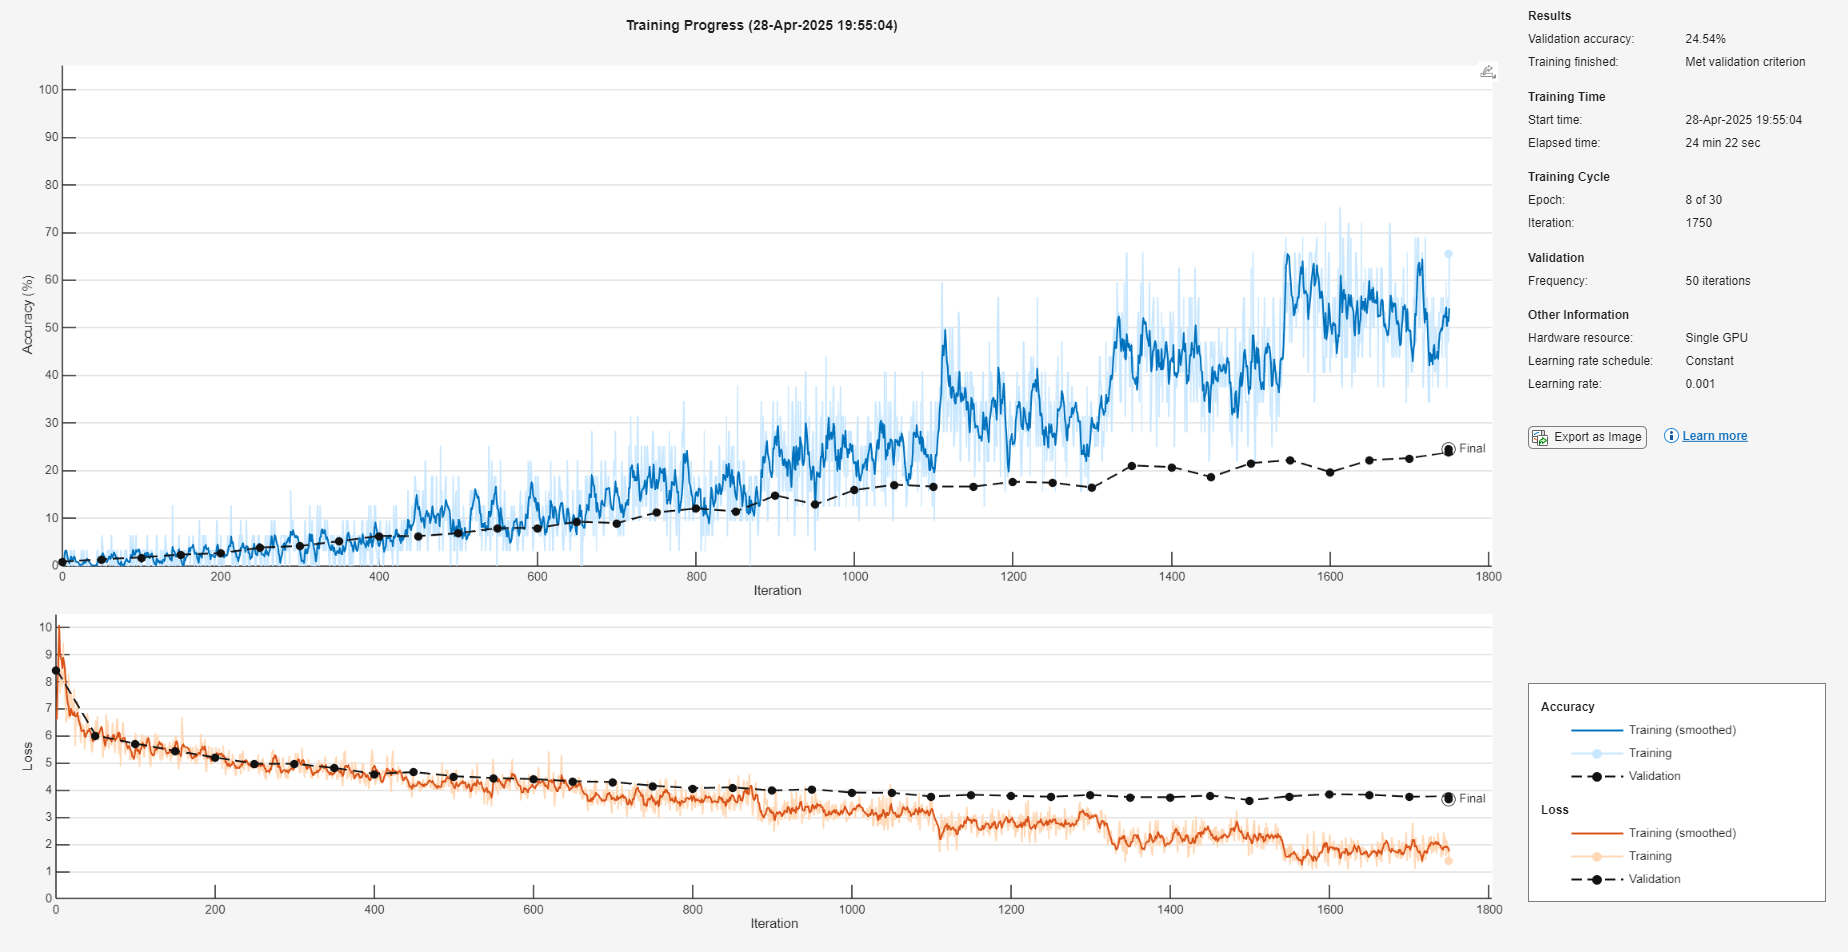

% % defines CNN layers
layers = [
    imageInputLayer([128 128 3])

    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 128, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 256, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 512, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)

    % globalAveragePooling2dLayer(Name="gap")
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
    ];



% sets training options
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MiniBatchSize', 32, ...
    'MaxEpochs', 30, ...
    'Verbose', true, ...
    'Shuffle', 'every-epoch', ...
    'VerboseFrequency', 1, ...
    'ValidationData', valCDS, ...
    "ValidationPatience",5, ...
    'Plots','training-progress');

% model training
simpleCNN = trainNetwork(trainCDS, layers, options);

## Evaluate the model

[trainAccuracy, trainPredictions] = evaluateClassifier(simpleCNN, trainCDS, trainingImageDS.Labels, true);
[valAccuracy, valPredictions] = evaluateClassifier(simpleCNN, valCDS, validationImageDS.Labels, true);
[accuracy, predictions] = evaluateClassifier(simpleCNN, testCDS, testImageDS.Labels, true);


disp("Train Accuracy = "+string(round(trainAccuracy*100, 1)))

Train Accuracy = 68.8


disp("Validation Accuracy = "+string(round(valAccuracy*100, 1)))

Validation Accuracy = 24.5


disp("Test Accuracy = "+string(round(accuracy*100, 1)))

Test Accuracy = 24.4


## Plot confusion matrix

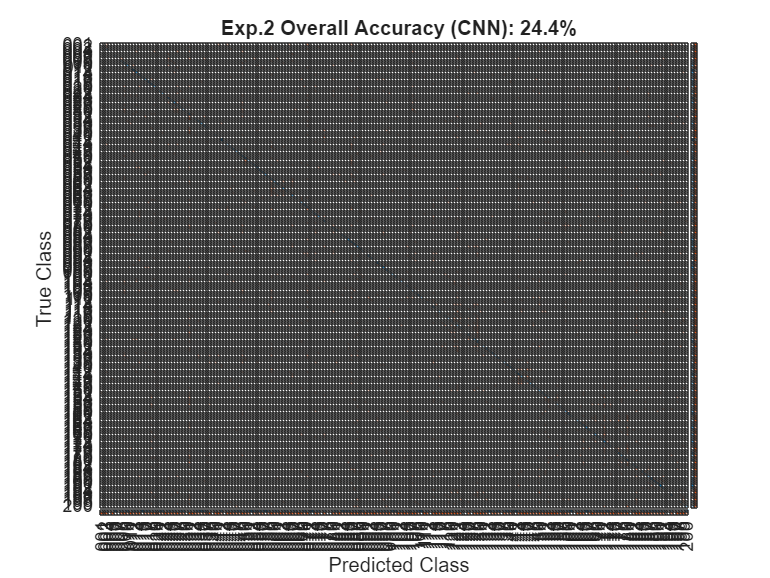

Classwise Recognition Rates:
         0
         0
   27.3000
         0
         0
   12.5000
         0
   11.1000
   33.3000
   41.7000
         0
  100.0000
   66.7000
   33.3000
    9.1000
   36.4000
   54.5000
   66.7000
   33.3000
         0
   33.3000
   27.3000
         0
   80.0000
    8.3000
   50.0000
    8.3000
   16.7000
    8.3000
         0
   50.0000
         0
    8.3000
   33.3000
   41.7000
   41.7000
   25.0000
         0
         0
    8.3000
         0
  100.0000
         0
    8.3000
   16.7000
   41.7000
   25.0000
   25.0000
   41.7000
   75.0000
   16.7000
    8.3000
   33.3000
   50.0000
   58.3000
   41.7000
   41.7000
    9.1000
   25.0000
   25.0000
   41.7000
         0
   41.7000
    8.3000
         0
   50.0000
    8.3000
         0
   16.7000
   41.7000
   33.3000
    8.3000
    8.3000
   33.3000
   45.5000
         0
   50.0000
         0
         0
   25.0000
   33.3000
         0
   25.0000
   33.3000
   58.3000
   58.3000
   58.3000
   41.7000
   

plotConfusionMatrix(testImageDS.Labels, predictions, "Exp.2 Overall Accuracy (CNN): " + string(round(accuracy*100, 1)) + "%");